**Simulation des EDPs **

# Aplication du méthode des volumes finis 

TPs effectués les jours 03/04 et 12/04/2023

Simulation des phénomènes de diffusion et de convection dans un champ scalaire

**Déric Augusto FRANÇA DE SALES**

mail: deric-augusto.franca-de-sales6@etu.univ-lorraine.fr

Codes produits dans la version R2020a du Simulink MATLAB en live script. 

## Introduction

### sur les EDPs

    Les EDP sont des équations qui prennent en compte une fonction parmi plusieurs dérivées partielles d'une fonction multivariable. Ainsi, plusieurs phénomènes physiques et concepts théoriques peuvent être modélisés mathématiquement à travers de ces équations aux dérivées partielles. Les EDPs sont utiles par example pour modéliser et simuler le comportement des ondes, les flux de chaleur, la dispersion des fluides et d'autres phénomènes dont le comportement spatial évolue dans le temps. 

    Un exemple d'application pratique est la modélisation de la dissipation de la chaleur dans les cartes de circuits imprimés. Grâce à ces outils mathématiques, il est possible de définir où la chaleur est concentrée et de prédire comment elle est dissipée.

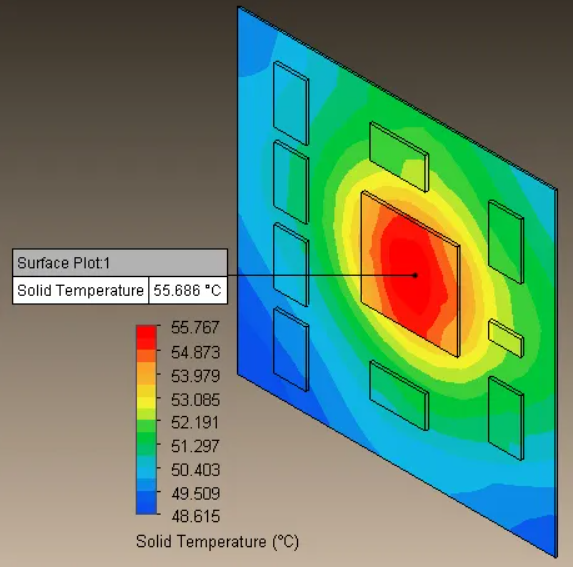

source : [https://semiengineering.com/what-i-learned-about-heatsinks-using-thermal-simulation/](https://semiengineering.com/what-i-learned-about-heatsinks-using-thermal-simulation/)

### les phénomènes de convection et de diffusion

    En mécanique des fluides, deux phénomènes qui se produisent qui permettent à la chaleur d’être transportée entre les régions dans un gradient sont la diffusion et la convection. La diffusion est le processus de transport de la chaleur d’un point à ses vignes en gradient. La convection, en revanche, est le mouvement du fluide généré par la différence de densité créée par la différence de température dans le fluide. Ainsi, lorsqu’une particule du fluide se déplace en fonction de cette différence de densité, elle transporte avec elle son niveau de chaleur. La convection est donc différente de la diffusion, puisqu’elle traite aussi du mouvement du fluide et du transfert de chaleur en fonction de ce mouvement, autant que dans la diffusion, cette chaleur est transportée avec le fluide statique (modélisé comme un solide parfait).

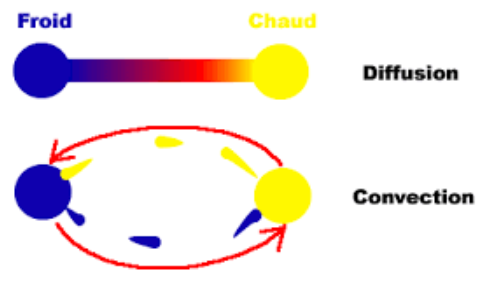

source : [http://www.ens-lyon.fr/RELIE/Centre_de_la_Terre/v2000/Working/thermique/convection.htm](http://www.ens-lyon.fr/RELIE/Centre_de_la_Terre/v2000/Working/thermique/convection.htm)

### le méthode des volumes finis

    La méthode des volumes finis est largement utilisée dans les simulations de mécanique des fluides. Tandis que la méthode des différences finies approxime les dérivées en utilisant les valeurs des nœuds, la méthode des volumes finis utilise le théorème de la divergence pour analyser une zone autour du point. Son nom même fait référence à la création d'un volume autour de chaque nœud du maillage créé pour analyser le fluide. 

    Ainsi, la méthode représente et évalue les EDP sous forme d'équations algébriques. Les intégrales de volume dans les EDP contenant un terme différentiel sont converties en intégrales de surface.

### problematique

    Le problème abordé dans ce compte rendu sera alors de résoudre l'équation de diffusion-dispersion suivante :

$\overrightarrow{\nabla} \cdot \left(\lambda \cdot \overrightarrow{\nabla} (\theta)\right) - \overrightarrow{\nabla}\cdot \left(\rho \cdot C_p \cdot \theta \cdot \overrightarrow{v} \right) = \rho \cdot C_{p} \cdot\frac{\partial \theta}{\partial t}$   (1)

où $\theta (x,y,t)$ est un scalaire passif qui est transporté par écoulement par le champ de vitesse : $\overrightarrow{v} (x,y,t) = u (x,y,t) \cdot \hat{i} + v(x,y,t) \cdot \hat{j}$ . Ce champ scalaire $\theta$ peut être vu comme un champ de température (chaleur) ou même como um camp de concentration (masse). Dans la rélation (1) on aura :

therme de diffusion :  $\overrightarrow{\nabla} \cdot \left(\lambda \cdot \overrightarrow{\nabla} (\theta)\right)$

therme de convection :  $- \overrightarrow{\nabla}\cdot \left(\rho \cdot C_p \cdot \theta \cdot \overrightarrow{v} \right)$

therme de stockage de la grandeur scalaire :  $\rho \cdot C_{p} \cdot\frac{\partial \theta}{\partial t}$

## Objectif

    Notre objectif est donc calculer l'évolution de $\theta$ au cours du temps à travers du méthode des volumes finis. Nous analiserons les cas :

- cas conductif pur en mettant la condition initiale au centre;

- schéma numérique conducto-convectif linéaire-linéaire.

## Discrétization du problème

### paramètres du maillage

Pour discrétizer la surface du champ scalaire $\theta$, nous créerons un maillage, dont les dimensions et l'ordre de numérotation seront définis selon le dessin ci-dessous :

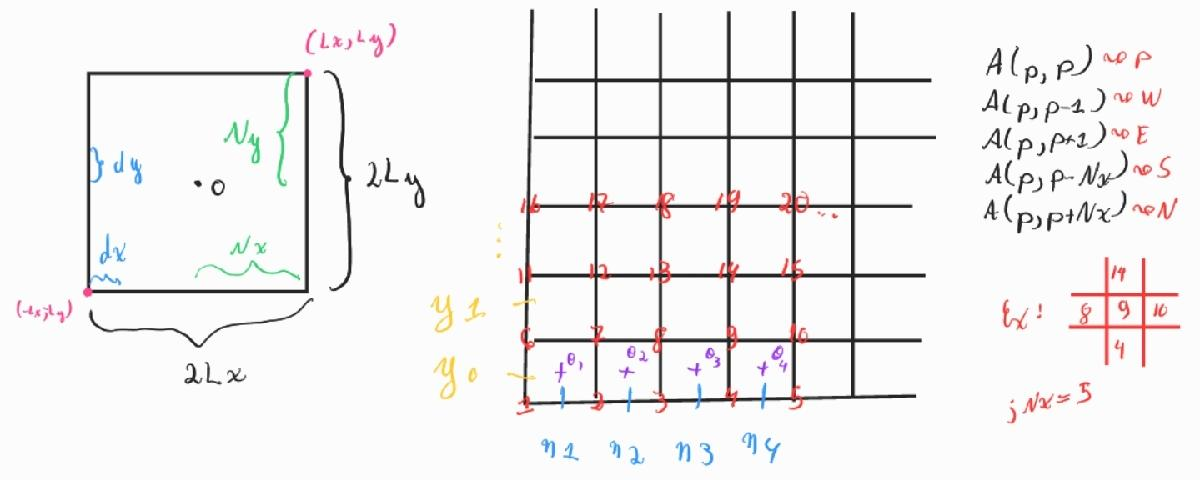

Dans notre maillage, nous créons un index dont le point de départ se situe dans le coin inférieur gauche du maillage et qui croît comme indiqué ci-dessus.  

Pour faciliter la navigation dans le maillage, outre le système d'index des positions définies, nous définirons également les positions nord, ouest (*west *en anglais) et est par rapport au point analysé sur le maillage :

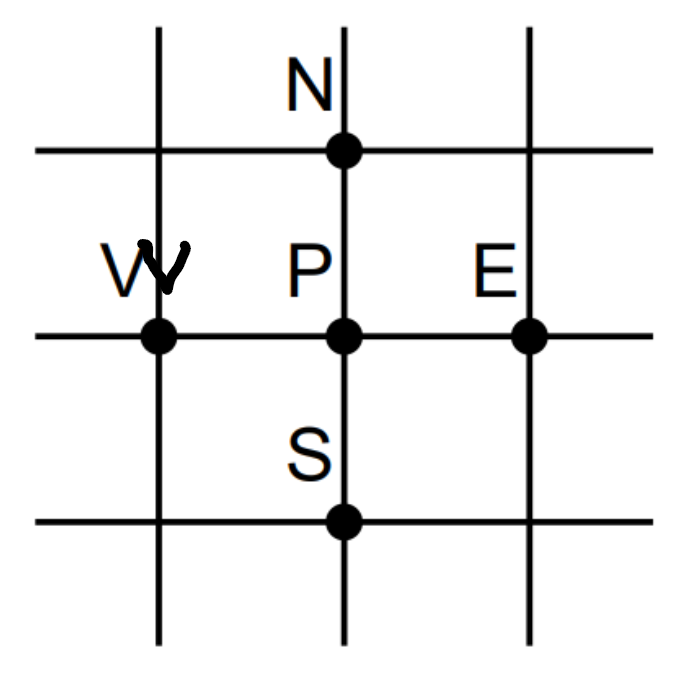

### discrétisation de l'EDP

Nous utillizerons aussi le système d'équations pour numériser l'équation (1) :  $\left \{
\begin{array}{rcl}
\theta^{(n+1)} &=& A \cdot \theta^{(n)} \\
\theta^{(0)} &=& \theta(t=0)
\end{array}
\right.$ 

où $A$ est une matrice de taille $N \times N$ et $\theta^{(n)}$ un vecteur colonne de taille $N$. 

Le domaine alors sur lequele nous aurons résoudre l'EDP est $\Omega = [-L_x, L_x] \times [-L_y, L_y]$, definissant : 

- 
$$h_x = \frac{2 L_x}{N_x}$$


- 
$$h_y = \frac{2L_y}{N_y}$$


- 
$$dt = \frac{T}{N_t}$$


### schéma de convection et diffusion 

En partant de la relation (1), nous aurons la formule finale du schéma de convection et diffusion donnée par : 

$o_p^{\;(n+1)} = A + B + C + D$    (2)   où :

A c'est la diffusion dans la direction x : $A = a \frac{\partial t}{\partial x^2} \left( \theta_W^{\;(n)} - 2 \theta_p^{\;(n)} + \theta_E^{\;(n)}\right)$

B dans la direction y : $B = a \frac{\partial t}{\partial y^2} \left( \theta_S^{\;(n)} - 2 \theta_p^{\;(n)}  + \theta_N^{\;(n)} \right)$

C la convection en x  : $C = - \frac{\partial t}{\partial x} \left( \frac{\theta_p^{\;(n)} + \theta_E^{\;(n)}}{2} \cdot u_E - \frac{\theta_p^{\;(n)}+\theta_W^{\;(n)}}{2} \cdot u_W \right)$

D en y : $D = - \frac{\partial t}{\partial y} \left( \frac{\theta_p^^{\;(n)} + \theta_N^{\;(n)}}{2}  \right)$

et aussi $a = \frac{\lambda}{p \cdot C_p}$ qui est la diffusivité thermique.

## Les donées du problème

clear all; close all; clc;

% la longueur
Lx = 1;
Ly = 1;

% nombre de points de discrétisation 
Nx = 128;
Ny = 128;
N = Nx + Ny;

% discritisation d'espace maillage
hx = 2*Lx/Nx;
hy = 2*Ly/Ny;

% pas de temps 
T = 0.1;
Nt = 1000;
dt = T/Nt;

% diffusivité thermique
a = 1;

% amplitude tourbillon = vitesse de diffusion
Um = 16; 

## Problème dans le cas purement conductif

Dans ce cas, nous ne travaillerons qu'avec les termes de diffusion de la relation (2). Alors, en thermes d'un point p dans le maillage, nous aurons : 


$$\theta_p^{\;(n+1)} = \theta_{p}^{\;(n)} 

+ a\frac{dt}{{h_{x}}^2 }\left( {\theta_W}^{(n)} - 2 {\theta_p}^{(n)} + {\theta_E}^{(n)} \right) 

+ a\frac{dt}{{h_{y}}^2 }\left( {\theta_S}^{(n)} - 2 {\theta_p}^{(n)} 
+ {\theta_N}^{(n)} \right)$$


Ensuite, en traduisant sous forme matriciel, nous aurons : 

$\theta^{\left(n+1\right)} =A\theta^{\left(n\right)}$ ;

$\theta^{\;\left(n\right)} =\left\lbrack \begin{array}{c}
{\theta_1 }^{\left(n\right)} \\
\vdots \\
{\theta_{N_y } }^{\left(n\right)} 
\end{array}\right\rbrack$ , $A=\left\lbrack \begin{array}{cccccc}
I-B & a\frac{\mathrm{dt}}{{h_y }^2 }I & 0 & \cdots  & \cdots  & 0\\
a\frac{\mathrm{dt}}{{h_y }^2 }I & I-B & a\frac{\mathrm{dt}}{{h_y }^2 }I & \ddots  & \ddots  & \vdots \\
0 & \ddots  & \ddots  & \ddots  & \ddots  & \vdots \\
\vdots  & \ddots  & \ddots  & \ddots  & \ddots  & 0\\
\vdots  & \cdots  & 0 & a\frac{\mathrm{dt}}{{h_y }^2 } & I-B & a\frac{\mathrm{dt}}{{h_y }^2 }\\
0 & \cdots  & \cdots  & 0 & a\frac{\mathrm{dt}}{{h_y }^2 } & I-B
\end{array}\right\rbrack$ ;  

$B=\left\lbrack \begin{array}{cccc}
2\cdot a\cdot \mathrm{dt}\cdot \left(\frac{1}{{h_x }^2 }+\frac{1}{{h_y }^2 }\right) & -a\frac{\mathrm{dt}}{{h_x }^2 } & 0 & 0\\
-a\frac{\mathrm{dt}}{{h_x }^2 } & \ddots  & \ddots  & 0\\
0 & \ddots  & \ddots  & -a\frac{\mathrm{dt}}{{h_x }^2 }\\
0 & 0 & -a\frac{\mathrm{dt}}{{h_x }^2 } & 2\cdot a\cdot \mathrm{dt}\cdot \left(\frac{1}{{h_x }^2 }+\frac{1}{{h_y }^2 }\right)
\end{array}\right\rbrack$.

### Création des matrices A et B

A = zeros(Nx*Ny, Nx*Ny);
temp = -a*dt/(hx^2)*ones(Nx-1,1);
B = 2*a*dt*(1/(hx^2) + 1/(hy^2))*eye(Nx) + diag(temp,1) + diag(temp,-1);

for j = 1:Ny
    p = (j-1)*Nx + 1; % indice p 
    A(p:p+Nx-1,p:p+Nx-1) = eye(Nx) - B; % on remplit la diagonal
    if j > 1 % si on n'est pas au bord gauche de la matrice A
        A(p:p-1+Nx,p-Nx:p-1) = a*dt/(hy)^2*eye(Nx); % on remplit la diagonale supérieure
    end
    if j < Ny % si on n'est pas au bord droit de la matrice A
        A(p:Nx+p-1,p+Nx:p+2*Nx-1) =a*dt/(hy)^2*eye(Nx); % on remplit la diagonale inférieure
    end
end
Acond = A % on stocke la matrice diffusion

Considerant que $\theta$ est nul au bord du domaine, nous aurons :

A(1:Nx,:) = zeros(Nx,Nx*Ny); % premier bloc de ligne à 0
A((Nx-1)*Ny+1:Ny*Nx,:) = zeros(Nx,Nx*Ny); % dernier bloc de ligne à 0

for j = 2:Ny-1 
    p = (j-1)*Nx + 1;
    A(p,:) = zeros(1,Nx*Ny);
    A(p+Nx-1,:) = zeros(1,Nx*Ny);
end

### Création du vecteur théta

theta0 = zeros(Nx*Ny,1);
x_vec = -Lx:hx:Lx-hx;
y_vec = -Ly:hy:Ly-hy;
x_vec = x_vec + hx/2*ones(1,size(x_vec,2));
y_vec = y_vec + hy/2*ones(1,size(y_vec,2));
for i = 1:Nx
    for j = 1:Ny
        p = i + (j-1)*Nx;
        y = -Ly + hy/2 + (j-1)*hy; 
        x = -Lx + hx/2 + (i-1)*hx; 
        if (x-Lx/2)^2 + y^2 <= (Lx/4)^2
            theta0(p,1) = 1;
        end
    end
end
theta = theta0;

### Résolution de l'EDP

for n = 1:Nt/4
    theta = A*theta;
    Thetam = reshape(theta,Nx,Ny);
    surf(x_vec,y_vec,Thetam);
    axis([-Lx,Lx,-Ly,Ly,0,1])
    drawnow
end

### Résultats

Le résultat de la simulation est la progression du phénomène d'écoulement (diffusion), comme le montre la séquence de figures ci-dessous :

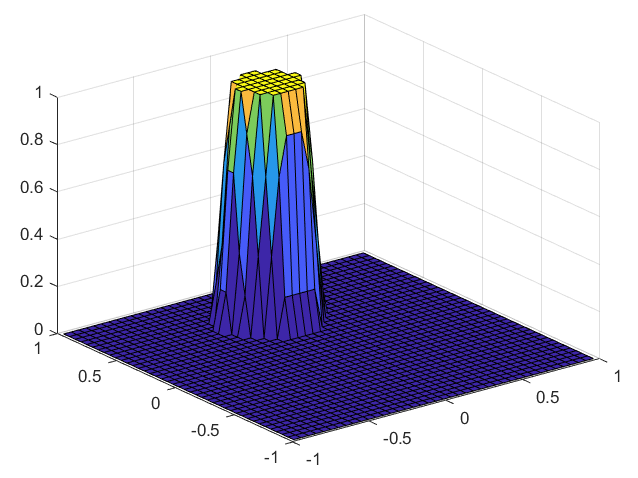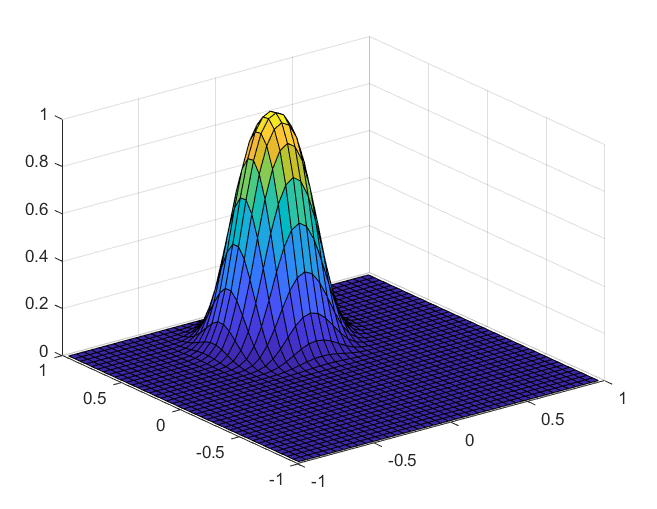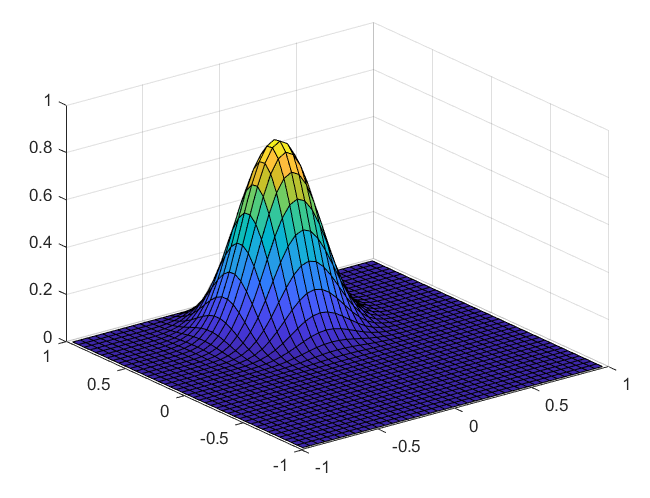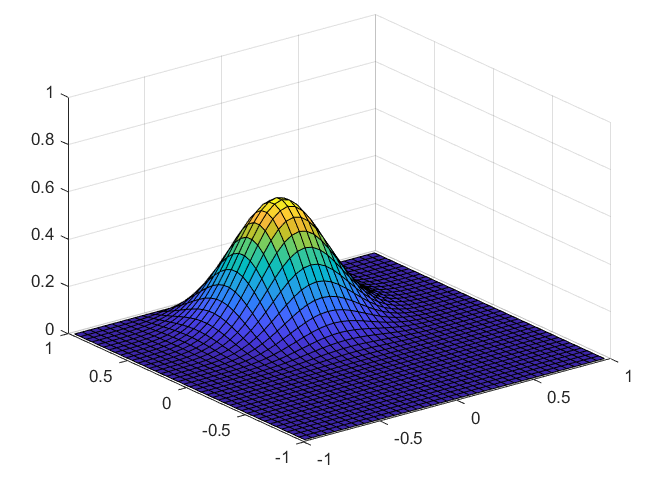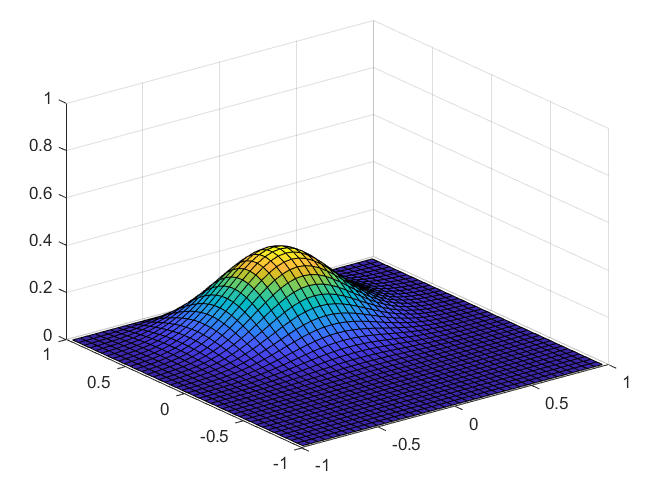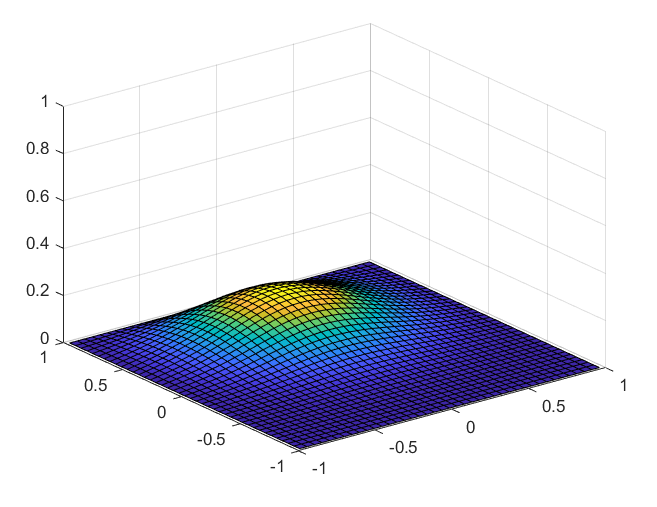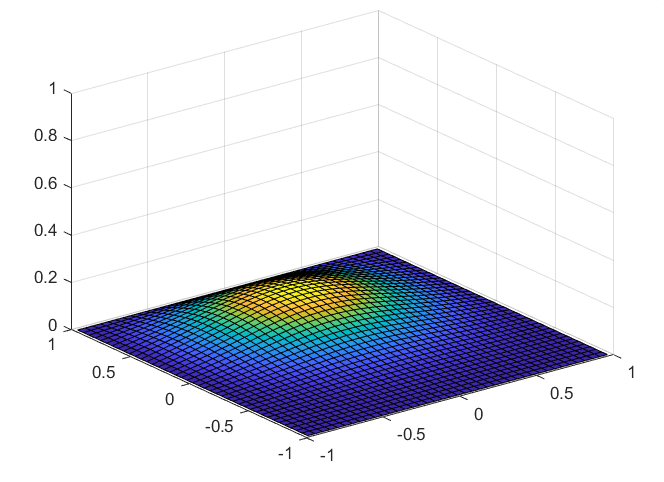

Dans cette simulation, la progression des images permet de voir comment la concentration d'énergie en un point du champ scalaire se disperse dans son voisinage. On constate que le champ scalaire commence par une région circulaire de haute énergie (module élevé), puis, au fil du temps, il s'atténue dans la région centrale et se propage aux alentours de manière symétrique. Ainsi, l'énergie qui était auparavant concentrée dans une région circulaire s'étendra au fil du temps jusqu'à ce qu'elle soit répartie de manière uniforme dans le champ scalaire représenté par la maille. 

## Schéma conducto-convectif linéaire-linéaire

    Cette fois, nous ferons les mêmes calculs que précédemment, mais en ajoutant le terme convectif de la relation (1).

u = @(x,y,Um) - Um*y/(x^2 + y^2);
v = @(x,y,Um) Um*x/(x^2 + y^2);

Aconv = zeros(Nx*Ny,Nx*Ny);
for j = 2:Ny-1
    for i = 2:Nx-1
        p = i + (j-1)*Nx;
        y = -Ly + hy/2 + (j-1)*hy; 
        x = -Lx + hx/2 + (i-1)*hx; 
        uE = u(x+hx/2,y,Um);
        uW = u(x-hx/2,y,Um);
        vN = v(x,y+hy/2,Um);
        vS = v(x,y-hy/2,Um);
        Aconv(p,p) = dt/2*((uW-uE)/hx + (vS-vN)/hy);
        Aconv(p,p+1) = -uE/(2*hx)*dt;
        Aconv(p,p-1) = uW/(2*hx)*dt; 
        Aconv(p,p+Nx) = -vN/(2*hy)*dt;
        Aconv(p,p-Nx) = vS/(2*hy)*dt;
    end
end
A = Aconv + Acond;

### Conditions aux limites

A(1:Nx,:) = zeros(Nx,Nx*Ny); % premier bloc de ligne à 0
A((Nx-1)*Ny+1:Ny*Nx,:) = zeros(Nx,Nx*Ny); % dernier bloc de ligne à 0
for j = 2:Ny-1
    p = (j-1)*Nx + 1;
    A(p,:) = zeros(1,Nx*Ny);
    A(p+Nx-1,:) = zeros(1,Nx*Ny);
end

### Résolution de l'EDP

for n = 1:Nt/4
 theta = A*theta;
 Thetam = reshape(theta,Nx,Ny);
 surf(x_vec,y_vec,Thetam);
 axis([-Lx,Lx,-Ly,Ly,0,1])
 drawnow
end

### Résultats

Le résultat de la simulation est la progression de la combinaison des phénomènes d'écoulement (diffusion) et convection, comme le montre la séquence de figures ci-dessous :

## 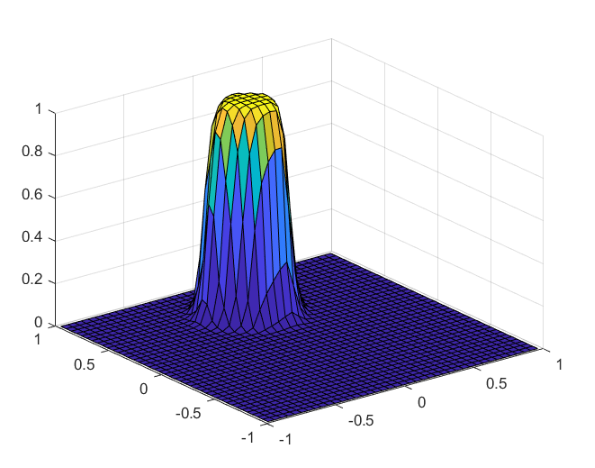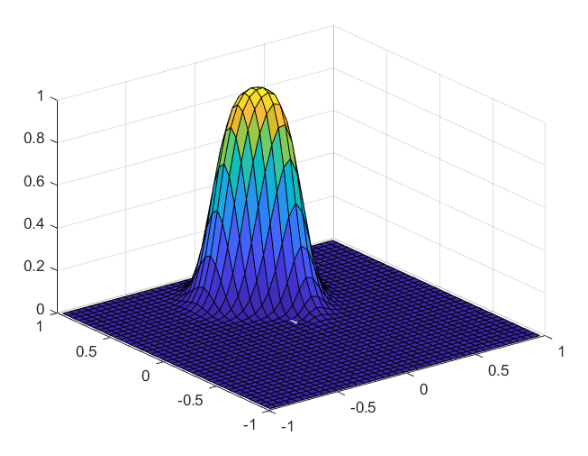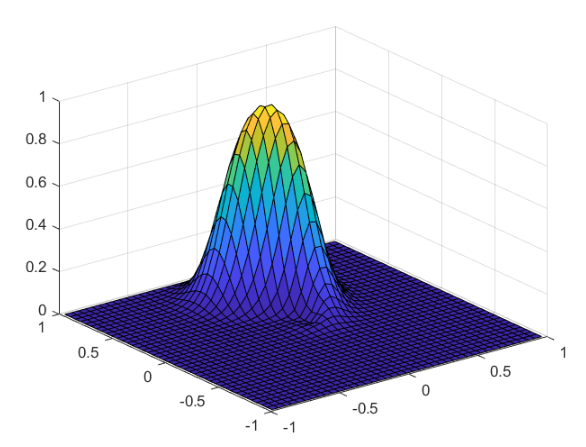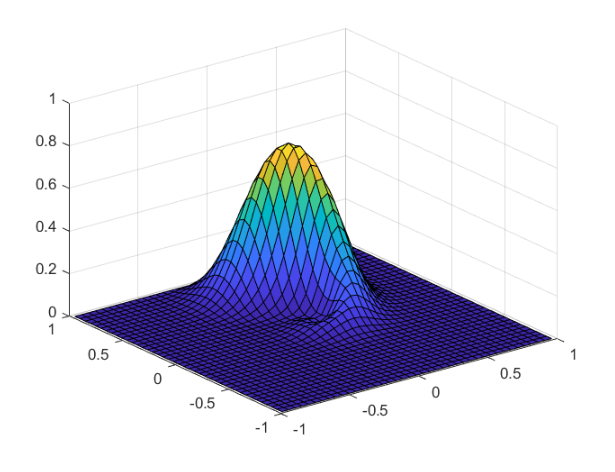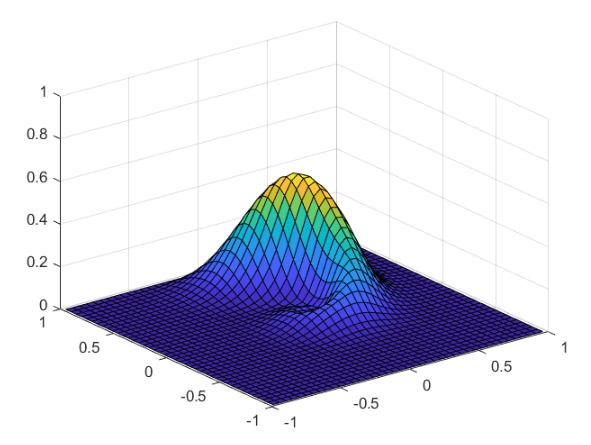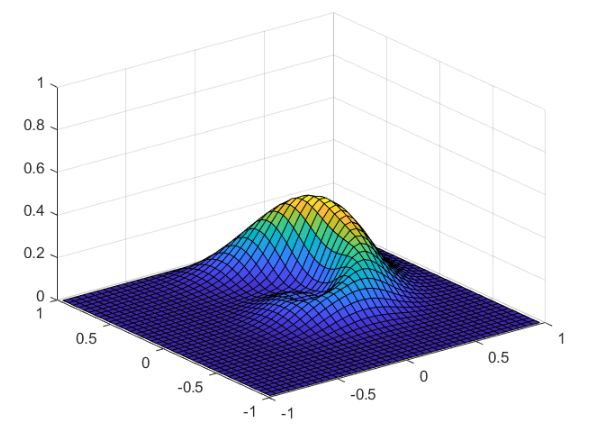

Dans cette simulation, contrairement aux résultats de la simulation effectuée précédemment, on peut noter la présence d'un tourbillon généré lors de la diffusion de l'énergie concentrique dans le maillage. Comme il s'agit d'une combinaison des phénomènes de diffusion et de convection, son comportement est analogue à la simulation où seul le phénomène de diffusion était pris en compte dans le modèle, mais cette fois-ci, ce vortex est créé. Le résultat final sera analogue, seule la progression de la simulation est différente avec cet élément supplémentaire pendant le processus de dispersion. 

## Schéma Upwind

Maintenant nous prenerons en compte le sens de l’écoulement pour l’évaluation de la fonction flux $f_e$sur la frontière.

u = @(x,y,Um) - Um*y/(x^2 + y^2);
v = @(x,y,Um) Um*x/(x^2 + y^2);

Aconv_up = zeros(Nx*Ny,Nx*Ny);
for j = 2:Ny-1
    for i = 2:Nx-1
        p = i + (j-1)*Nx;
        y = -Ly + hy/2 + (j-1)*hy; %ordonnee du maillon
        x = -Lx + hx/2 + (i-1)*hx; %abscisse du maillon
        uE = u(x+hx/2,y,Um);
        uW = u(x-hx/2,y,Um);
        vN = v(x,y+hy/2,Um);
        vS = v(x,y-hy/2,Um);
        Aconv_up(p,p) = -dt*((max(0,uE) - max(0,uW))/hx + (max(0,vN) - max(0,vS))/hy);
        Aconv_up(p,p+1) = -dt/hx*min(0,uE);
        Aconv_up(p,p-1) = dt/hx*min(0,uW);
        Aconv_up(p,p+Nx) = -dt/hy*min(0,vN);
        Aconv_up(p,p-Nx) = dt/hy*min(0,vS);
    end
end
A_up = Aconv_up + Acond;

### Conditions aux limites

A_up(1:Nx,:) = zeros(Nx,Nx*Ny); % premier bloc de ligne à 0
A_up((Nx-1)*Ny+1:Ny*Nx,:) = zeros(Nx,Nx*Ny); % dernier bloc de ligne à 0
for j = 2:Ny-1
 p = (j-1)*Nx + 1;
 A_up(p,:) = zeros(1,Nx*Ny);
 A_up(p+Nx-1,:) = zeros(1,Nx*Ny);
end

### Résolution de l'EDP

for n = 1:Nt
 theta = A_up*theta;
 Thetam = reshape(theta,Nx,Ny);
 surf(x_vec,y_vec,Thetam);
 axis([-Lx,Lx,-Ly,Ly,0,1])
 drawnow
end

### Résultats

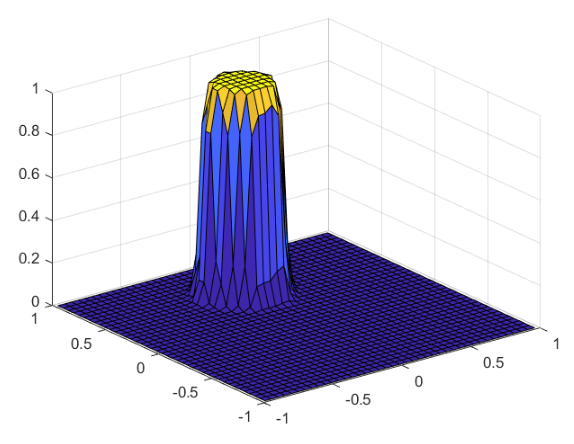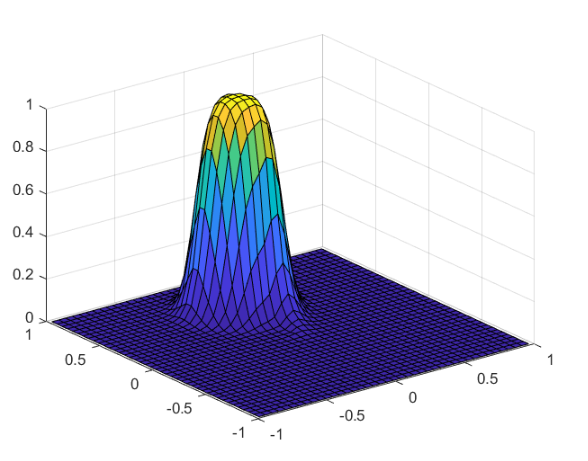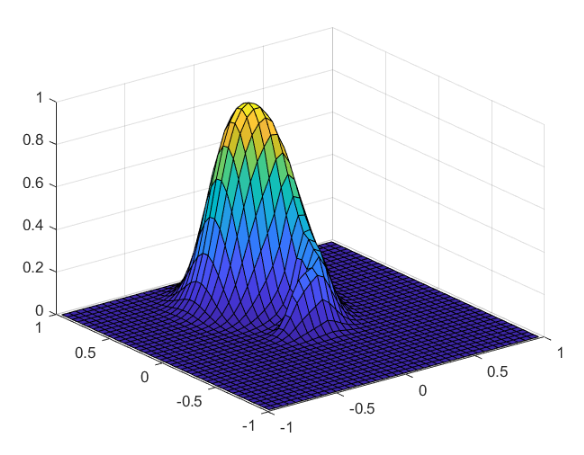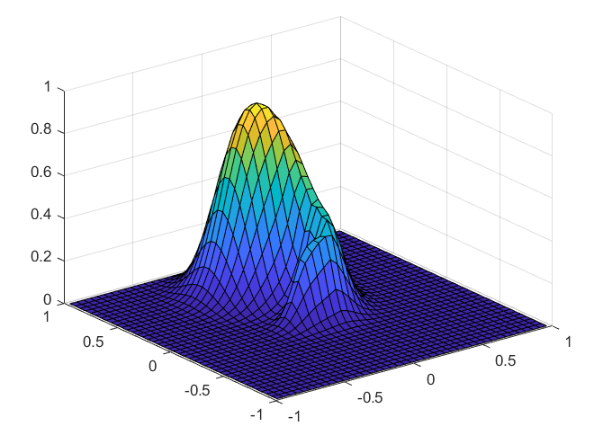

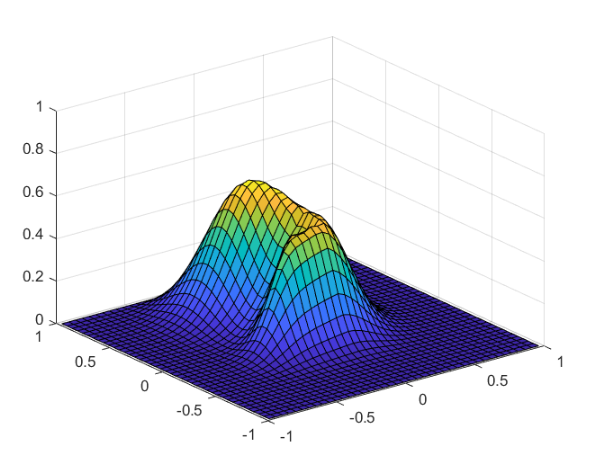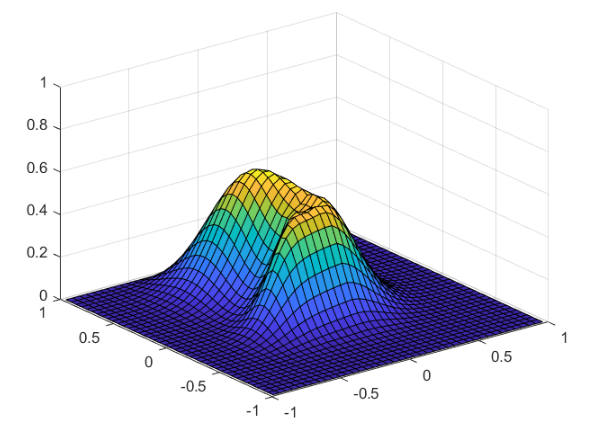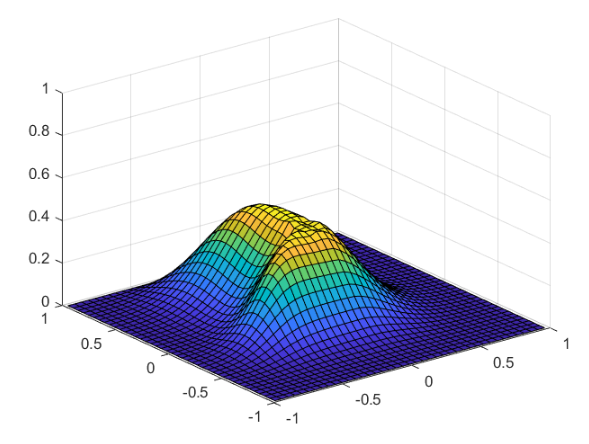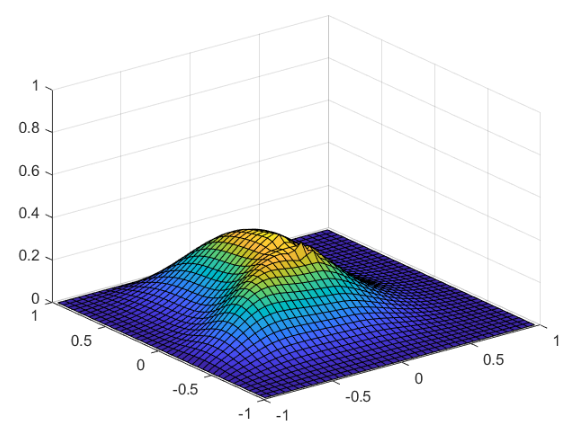

## Étude de stabilité des schémas

Dans cette partie, nous ferons varier les paramètres de simulation afin d'évaluer l'impact sur les résultats. Nous notons que la simulation peut ne pas fonctionner correctement lorsque nous fixons un pas de temps trop important, ce qui fait que les effets étudiés ne sont pas bien appliqués dans le temps. 

En changeant également le nombre de points du maillage créé, on se rend compte que plus le nombre de points est important, plus le système se rapproche de la réalité. D'autre part, en diminuant le nombre de points, nous ne sommes souvent même pas en mesure de percevoir les effets étudiés, en raison de la faible résolution de la simulation. 

Il convient de préciser que les simulations présentées précédemment ont été effectuées avec les paramètres : Um = 10 , Nx = 41  et Ny = 41. 

Lors de la simulation avec les paramètres Um = 1,5 , Nx = 99  et Ny = 99 , nous obtenons :

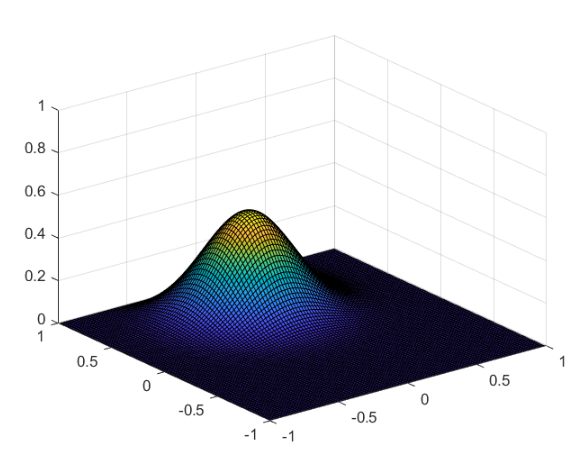

En raison du grand nombre de points utilisés dans le maillage, la résolution de la simulation est élevée, ce qui implique un modèle plus proche de la continuité, mais aussi une simulation plus lourde, qui nécessite davantage de traitement de la part de la machine qui l'exécute. En revanche, comme nous appliquons une amplitude de tourbillon très faible, nous ne sommes pas en mesure de remarquer le tourbillon généré par l'effet de convection dans les simulations qui l'intègrent.  

En simulant avec les paramètres Um = 10 ; Nx = 99 ; Ny = 99, on obtient :

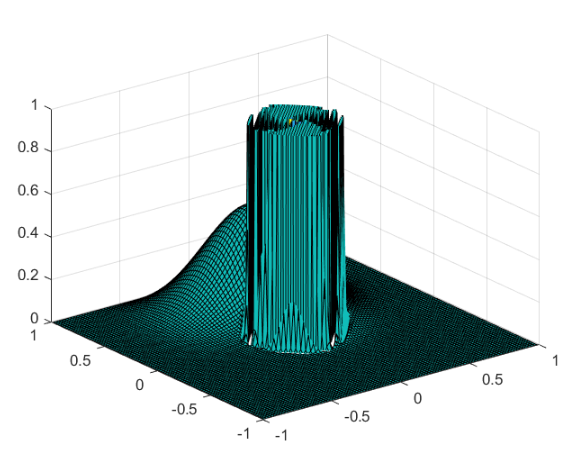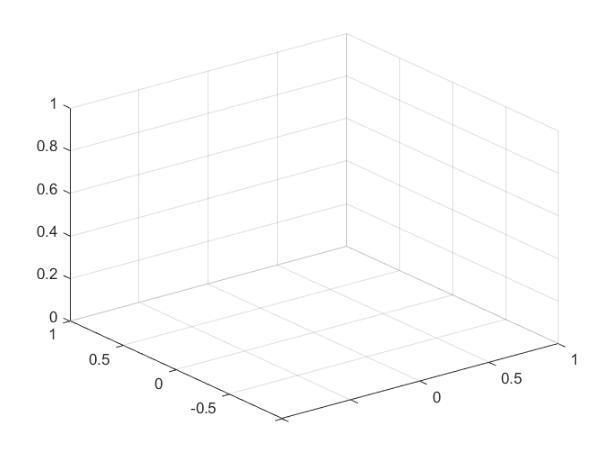

Maintenant, en continuant avec le même nombre de divisions dans le maillage mais en augmentant l'amplitude du tourbillon, nous observons des problèmes dans les simulations qui incluent l'effet de la convection. Comme vous pouvez le voir ci-dessus, au moment où le tourbillon commence à être généré, le système commence à diverger, puis la simulation s'arrête complètement. Ainsi, avec ces paramètres, nous pouvons voir que le système est très instable.

## Conclusion

En conclusion, nous avons réussi à réaliser des simulations numériques du transport d'un scalaire passif dans un domaine bidimensionnel, en appliquant la méthode des volumes finis. Nous élucidons la base théorique de la modélisation mathématique et son application pratique, discutons du modèle mathématique du problème et l'appliquons à des schémas impliquant la convection et la diffusion, avec différents paramètres. Nous avons remarqué que la modification des paramètres peut entraîner une divergence dans la simulation ou son instabilité. 

Tout au long des exercices, nous avons également pu comprendre la différence entre les trois schémas et comment les termes de diffusion et de convection modifient l'évolution du champ scalaire dans le temps. Nous nous rendons compte qu'en choisissant les bons paramètres pour que la simulation soit stable, nous sommes capables de remarquer le tourbillon dans le champ scalaire qui est généré par l'effet de convection. 

Ainsi, l’étude de cette problématique a permis de comprendre les caractéristiques de différents schémas numériques et comment le paramétrage de ces schémas a un impact sur leur résultat. Il a été alors possible de voir dans la pratique une application des équations dérivées partielles, qui comme discuté précédemment a une grande utilisation dans les applications de modélisation par exemple des simulations de champs électromagnétiques, simulation générale des fluides et divers problèmes techniques.